# **Td1**

**1/ Créer une image 200*200**

I(1:200,1:200,1) = 255;% Canal rouge
I(1:200,1:200,2) = 255;% Canal vert
I(1:200,1:200,3) = 255;% Canal bleu
I% Afficher la matrice de l'image

I = I(:,:,1) =

   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255

imwrite(I,'im1.jpg')% Sauvegarder l'image en tant que 'im1.jpg'

imshow(I) % Afficher l'image

**Image rouge**

I(1:200,1:200,3) = 0; % Mettre le canal bleu à 0
I(1:200,1:200,2) = 0; % Mettre le canal vert à 0
imwrite(I,'im2.jpg') % Sauvegarder l'image en tant que 'im2.jpg'
disp('Image rouge') % Afficher un message

Image rouge


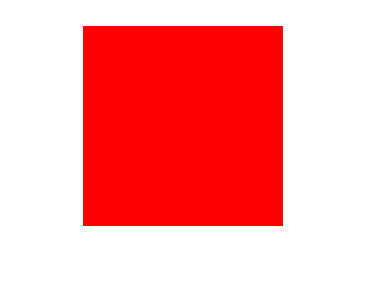

imshow(I) % Afficher l'image

**Image 2**

R = 120; G = 0; B = 120; % Définir les valeurs RGB
I2(1:200,1:200,1) = R; % Canal rouge
I2(1:200,1:200,2) = G; % Canal vert
I2(1:200,1:200,3) = B; % Canal bleu
imwrite(I2,'im3.jpg') % Sauvegarder l'image en tant que 'im3.jpg'
disp('Image rose') % Afficher un message

Image rose


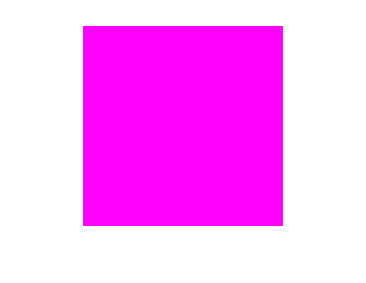

imshow(I2) % Afficher l'image

**Transformer en gris**

GRAY(1:200,1:200,1) = 0.5; % Canal rouge
GRAY(1:200,1:200,2) = 0.5; % Canal vert
GRAY(1:200,1:200,3) = 0.5; % Canal bleu
imwrite(GRAY,'im4.jpg') % Sauvegarder l'image en tant que 'im4.jpg'
disp('Image grise') % Afficher un message

Image grise


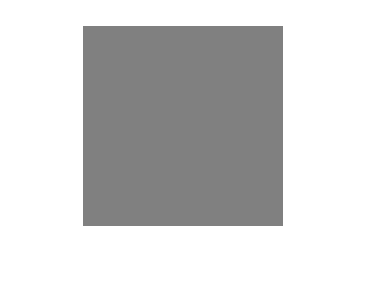

imshow(GRAY) % Afficher l'image

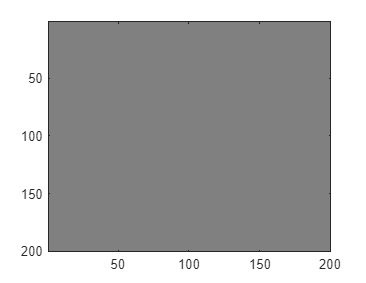

image(GRAY) % Afficher l'image

**Application de l'algorithme**

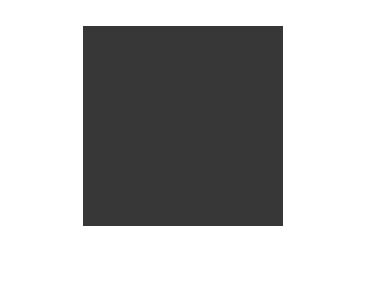

Ig2 = imread('im1.jpg'); % Lire l'image 'im1.jpg'
I3 = Ig2; % Copier l'image
for i = 1:20
    I3(:,:,1) = Ig2(:,:,1)-i*10; % Réduire la valeur du canal rouge
    I3(:,:,2) = Ig2(:,:,2)-i*10; % Réduire la valeur du canal vert
    I3(:,:,3) = Ig2(:,:,3)-i*10; % Réduire la valeur du canal bleu
    imshow(I3) % Afficher l'image
    pause(0.5) % Pause de 0.5 secondes
end

On a une image dont les pixels diminuent et passe de 255 à 0.

Ce qui donne une image qui passe de blanc à noire.